**0. Preparation**

clear, close all,clc;

    add other folders' path

    **! Be careful.**

    This live script must be run at the path of  "../FT-STFT-WT-HHT/WT"

    Problems or accidents will happen when current directory.

path(path, '../SourceSignal'); % raw data of experiments -- folder
path(path, '../FT');           % functions or example scripts of Fourier Transformation

**1. Read the raw data of experiment.**

data = csvread('dEMG4Chs.csv', 1, 0);
size(data)

ans =      1850000           8

    explanation of data struct -- [t, ch1, t, ch2, t, ch3, t, ch4]

**2. Fourier Transformation**

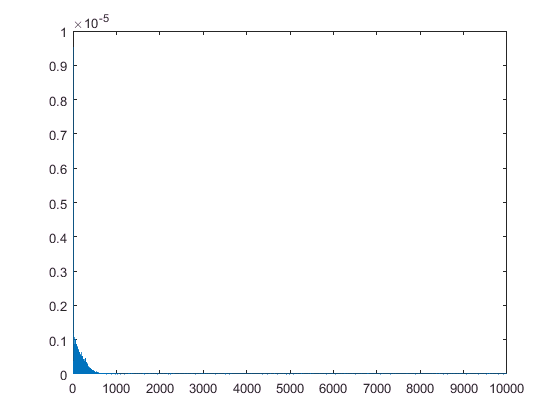

Fs = 20000; % 20K sampling frequency
[M, P, f] = FourierAnalysis(data(:,2), Fs);
plot(f, M)